%% NMR Titration: Fit Guest Shift (1:2 Binding + G Dimerization)
clear; clc;

%% === INPUT DATA ===
% Total host and guest concentrations (in mmol/L)
Htot = [0.228, 0.228, 0.228, 0.228, 0.228, 0.228]' * 1e-3; % e.g., Host conc. in unit of mM constant
Gtot = [0.2223, 1.1115, 1.64502, 2.46582, 3.04038, 4.67856]' * 1e-3; % Guest conc. in unit of mM

% Experimental chemical shifts of Guest (ppm) — replace with your real data
delta_obs_exp = [8.5556, 8.5441, 8.5322, 8.5206, 8.5014,8.4819]';

% Known values
Kdimer = 1.51;        % M^-1, guest dimerization
%delta_G = 10.1989;       % ppm, free guest
%delta_G2 = 10.1727;      % ppm, dimer

%% === Fit Parameters ===
% Initial guess for: [log10(K1), log10(K2), delta_G, delta_G2, delta_HG, delta_HG2]
params0 = [0, 3,10.19, 10.19, 10.19, 10.19]; % Initial guess: [log10(K1), log10(K2), delta_G, delta_G2]
lb = [-2, 1, 10, 10, 10.0051, 10.1];          % lower bounds for fitting
ub = [10, 10, 10.5, 10.5, 10.5, 10.5];      % upper bounds for fitting

options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9);
[params_fit,~,residual,~,~,~,J] = lsqcurvefit(@(p,x) model_guest_shift(p,x,Kdimer), ...
    params0, [Htot Gtot], delta_obs_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          7        0.00048353                           0.0205
     1         14        0.00048353         2.18375           0.0205      
     2         21       2.82623e-05        0.545937          0.00246      
     3         28       2.61884e-06        0.383936         1.02e-05      
     4         35       2.61884e-06        0.810792         1.02e-05      
     5         42       1.99151e-06        0.202698         3.68e-05      
     6         49       1.67665e-06        0.221485         0.000207      
     7         56       9.65832e-07       0.0636268         0.000105      
     8         63       9.12471e-07       0.0175744         8.49e-05      
     9         70       9.04365e-07     5.22942e-05         3.75e-06      
    10         77       8.98093e-07      0.00147354         3.38e-06      
    11         84        8.9777e-07     0


%% === Output Results ===
K1 = 10^params_fit(1);
K2 = 10^params_fit(2);
delta_G = params_fit(3);
delta_G2 = params_fit(4);
delta_HG = params_fit(5); 
delta_HG2 = params_fit(6);

fprintf('\nFitted Parameters:\n');


Fitted Parameters:


fprintf('K1 (H + G ⇌ HG)     = %.2e M^-1\n', K1);

K1 (H + G ⇌ HG)     = 3.59e+01 M^-1


fprintf('K2 (HG + G ⇌ HG2)   = %.2e M^-1\n', K2);

K2 (HG + G ⇌ HG2)   = 1.45e+03 M^-1


fprintf('delta_G (Free Guest) = %.5f ppm\n', delta_G);

delta_G (Free Guest) = 10.19884 ppm


fprintf('delta_G2 (Guest Dimer) = %.5f ppm\n', delta_G2);

delta_G2 (Guest Dimer) = 10.17500 ppm


fprintf('delta_HG (HG binding) = %.5f ppm\n', delta_HG);

delta_HG (HG binding) = 10.00510 ppm


fprintf('delta_HG2 (HG2 binding) = %.5f ppm\n', delta_HG2);

delta_HG2 (HG2 binding) = 10.13192 ppm


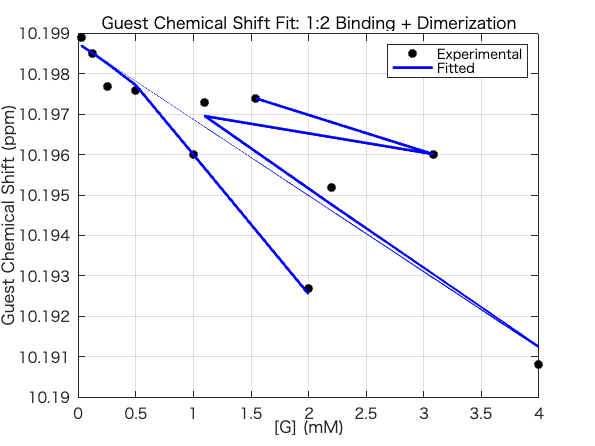


%% === Plot Results ===
delta_fit = model_guest_shift(params_fit, [Htot Gtot], Kdimer);

figure;
plot(Gtot*1e3, delta_obs_exp, 'ko', 'MarkerFaceColor', 'k'); hold on;
plot(Gtot*1e3, delta_fit, 'b-', 'LineWidth', 2);
xlabel('[G] (mM)');
ylabel('Guest Chemical Shift (ppm)');
legend('Experimental', 'Fitted');
title('Guest Chemical Shift Fit: 1:2 Binding + Dimerization');
grid on;


%% === Optional Output Table ===
fprintf('\nPoint-by-point summary:\n');


Point-by-point summary:


fprintf('%6s %6s %10s %10s\n', '[H] (mM)', '[G] (mM)', 'δ_obs', 'δ_fit');

[H] (mM) [G] (mM)      δ_obs      δ_fit


for i = 1:length(Gtot)
    fprintf('%6.4f %6.4f %10.4f %10.4f\n', Htot(i)*1e3, Gtot(i)*1e3, delta_obs_exp(i), delta_fit(i));
end

0.3658 2.0000    10.1927    10.1926
0.1829 1.0000    10.1960    10.1960
0.0915 0.5000    10.1976    10.1977
0.0457 0.2500    10.1977    10.1983
0.0229 0.1250    10.1985    10.1985
0.0057 0.0312    10.1989    10.1987
0.3700 4.0000    10.1908    10.1912
0.1850 2.2000    10.1952    10.1948
0.0925 1.1000    10.1973    10.1970
0.0617 3.0833    10.1960    10.1960
0.0308 1.5417    10.1974    10.1974



% Calculate R-squared
SS_res = sum((delta_obs_exp - delta_fit).^2);
SS_tot = sum((delta_obs_exp - mean(delta_obs_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.6f\n', R_squared);

R-squared: 0.985503



%% === Output Table of Species and Shifts ===
% Calculate concentrations of species
N = length(Gtot);
species_table = table('Size', [N 7], ...
    'VariableTypes', repmat({'double'}, 1, 7), ...
    'VariableNames', {'Htot_mM', 'Gtot_mM', '[HG]_uM', '[HG2]_uM', '[G2]_uM', 'δ_obs', 'δ_fit'});

for i = 1:N
    Ht = Htot(i); Gt = Gtot(i);
    x0 = [Gt/2, 1e-6, 1e-6, 1e-6]; % [G, HG, HG2, G2]
    sol = fsolve(@(x) equations(x, Gt, Ht, 10^params_fit(1), 10^params_fit(2), Kdimer), x0, ...
    optimoptions('fsolve','Display','off'));
    G = sol(1); HG = sol(2); HG2 = sol(3); G2 = sol(4)
    Del_fit = ( G * params_fit(3) + 2* G2 * params_fit(4) + 2* HG2 * params_fit(6) + HG * params_fit(5)) / Gt;

    species_table{i,:} = [Ht*1e3, Gt*1e3, HG*1e6, HG2*1e6, G2*1e6, delta_obs_exp(i), Del_fit];
end

G2 = 4.8150e-05

G2 = 1.3655e-05

G2 = 2.7638e-06

G2 = 6.9919e-07

G2 = 1.7575e-07

G2 = 1.1029e-08

G2 = 1.7191e-04

G2 = 6.0836e-05

G2 = 1.6759e-05

G2 = 1.1901e-04

G2 = 3.2589e-05


disp('Concentration Table (μM, mM, ppm):');

Concentration Table (μM, mM, ppm):


disp(species_table);

     Htot_mM     Gtot_mM     [HG]_uM     [HG2]_uM    [G2]_uM     δ_obs     δ_fit 
    _________    _______    _________    ________    ________    ______    ______

       0.3658          2       19.037      49.195       48.15    10.193    10.193
       0.1829          1       5.7675      7.9607      13.655    10.196    10.196
      0.09145        0.5       1.5706     0.92034      2.7638    10.198    10.198
     0.045725       0.25      0.39443     0.24981     0.69919    10.198    10.198
     0.022863      0.125     0.097064    0.098642     0.17575    10.198    10.199
    0.0057156    0.03125    0.0052584    0.022706    0.011029    10.199    10.199
         0.37          4       26.119      127.99      171.91    10.191    10.191
        0.185        2.2       10.386       30.18      60.836    10.195    10.195
       0.0925        1.1        3.189       4.877      16.759    10.197    10.197
     0.061667     3.0833       4.1109      16.687      119.01    10.196    10.196
     0.030833  

function delta_obs = model_guest_shift(params, xdata, Kdimer)
    K1 = 10^params(1);
    K2 = 10^params(2);
    delta_G = params(3);  % Free guest shift
    delta_G2 = params(4); % Dimer guest shift
    delta_HG = params(5); % HG guest shift
    delta_HG2 = params(6); % HG2 guest shift

    Htot = xdata(:,1);
    Gtot = xdata(:,2);
    N = length(Htot);
    delta_obs = zeros(N,1);

    for i = 1:N
        Ht = Htot(i); Gt = Gtot(i);
        x0 = [Gt/2, 1e-6, 1e-6, 1e-6]; % Initial guess for [G, HG, HG2, G2]

        sol = fsolve(@(x) equations(x, Gt, Ht, K1, K2, Kdimer), x0, ...
            optimoptions('fsolve','Display','off'));

        G = sol(1); HG = sol(2); HG2 = sol(3); G2 = sol(4);

        % Guest chemical shift is weighted over all guest-containing species
        numerator = G * delta_G + 2 * G2 * delta_G2 + HG * delta_HG + 2* HG2 * delta_HG2;
        denominator = G + 2 * G2 + HG + 2 * HG2;

        delta_obs(i) = numerator / denominator;
    end
end

function F = equations(x, Gtot, Htot, K1, K2, Kdimer)
    G = x(1); HG = x(2); HG2 = x(3); G2 = x(4);
    H = Htot - HG - HG2;

    F(1) = HG  - K1 * H * G;
    F(2) = HG2 - K2 * HG * G;
    F(3) = G2  - Kdimer * G^2;
    F(4) = Gtot - (G + HG + 2 * HG2 + 2* G2);
end